# plotting

% load("MVL\sim_data.mat","struc_powers")

## extracting variables



t = struc_powers.time;

p_LOAD = struc_powers.signals(1).values(:,1);
p_GRID = struc_powers.signals(1).values(:,2);
p_GFM = struc_powers.signals(1).values(:,3);
p_GFM_ref = struc_powers.signals(1).values(:,4);


## Visualize



plotTitle = "SCR: " + SCR_grid + " X/R: " + X_R_ratio_grid

plotTitle = "SCR: 1.5 X/R: 5"

figName = "SCR"+num2str(floor(SCR_grid))+"_" +num2str(mod(SCR_grid,1)*10)+"_" +"XR"+X_R_ratio_grid

figName = "SCR1_5_XR5"

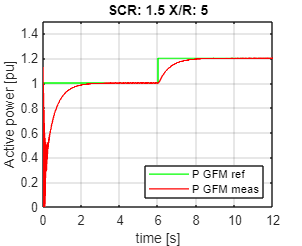

figure('Name','Active_Power'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
hold on
grid on
box on

plot(t,p_GFM_ref,'g-',LineWidth=1);
plot(t,p_GFM,'r-',LineWidth=1);
title(plotTitle,Interpreter="tex")

axis([0 12 0 1.5])
legend('P GFM ref', 'P GFM meas',Location='southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('Active power [pu]')
ay = gca;
ay.YTick = 0:0.2:1.5;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = "Active_Power"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = "Active_Power"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)